clear;clc;close all
thresh=0.5;
all_score=[];
load a.mat
load detectionResults.mat
[ap,recall_matlab,precision_matlab] = evaluateDetectionPrecision(detectionResults, a, 0.5);
ap

ap = 0.7712

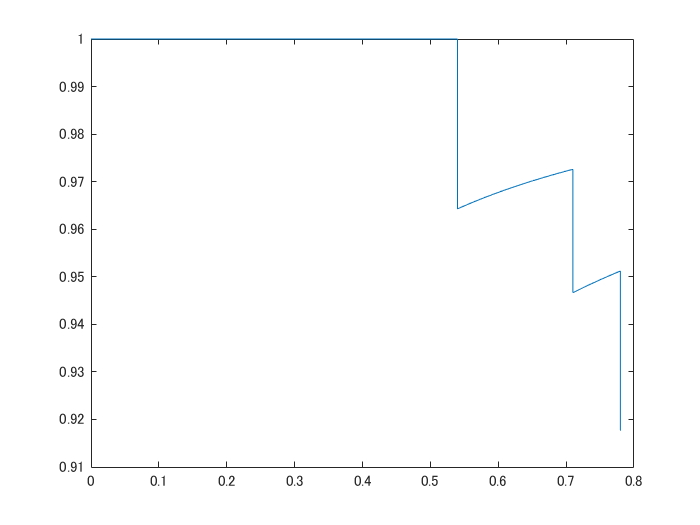

figure;plot(recall_matlab,precision_matlab)


num=0;
for i=1:size(detectionResults,1)
    scoreAll=detectionResults(i,2);
    scoreAll=numel(scoreAll.Scores{1});
    num=num+scoreAll;
end
num

num = 85



numgt=0;
aa=a.vehicle;
for i=1:size(a,1)
    bb=aa{i};
    numgt=numgt+size(bb,1);
end
numgt

numgt = 100


bbox_ind=1;
for i=1:size(detectionResults,1)
    bboxes=detectionResults(i,1);
    bboxes_i=bboxes.Boxes{1};
    
    
    % scoreを追加
    scores=detectionResults(i,2);
    scores_i=scores.Scores;
    if size(bboxes_i,1)>0
        for j=1:size(bboxes_i,1)
            b=a.vehicle;
            dummy=bboxes_i(j,:);
            score_j=scores_i{1};
            catb=cat(1,b{i});
            overlapRatio = bboxOverlapRatio(dummy,catb,'Union');
            overlapRatioMax = max(overlapRatio);
            if overlapRatioMax > thresh
                all_score(bbox_ind)=score_j(j);
                iscorrect(bbox_ind)=1;
            else
                all_score(bbox_ind)=score_j(j);
                iscorrect(bbox_ind)=0;
            end
                if bbox_ind==26
                    overlapRatioMax
                    j
                end
                bbox_ind=bbox_ind+1;
                
        end
    end

end

overlapRatioMax = 0.6348

j = 1

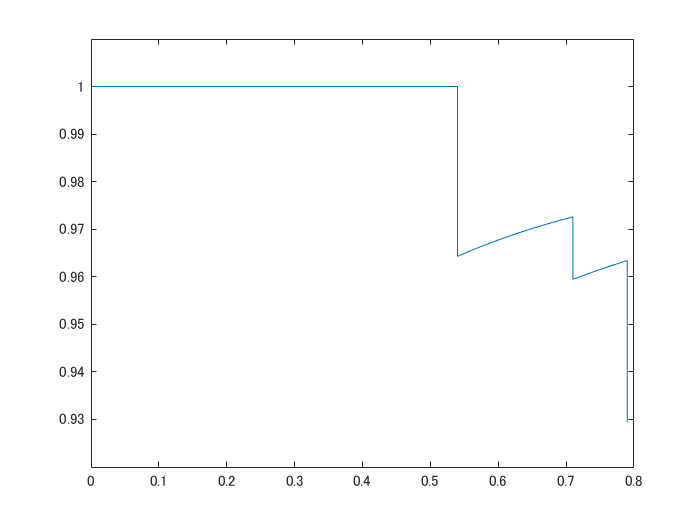

recall=0;
precision=1;

[all_score,scoreInd] = sort(all_score,'descend');
iscorrect=iscorrect(scoreInd);
for k=1:bbox_ind-1
    if iscorrect(k)==1
        recall(k+1)=recall(k)+1/numgt;
        precision(k+1)=sum(iscorrect(1:k)/k);
    else
        recall(k+1)=recall(k);
        precision(k+1)=sum(iscorrect(1:k)/k);
    end
end

figure;plot(recall,precision)


v=1;ap=0;
for l=1:numel(precision)-1
    precision_i=precision(l);
    ap=ap+(recall(l+1)-recall(l))*precision_i;
end
ap

ap = 0.7816